# Расстояние между функциями

## Красницкий Никита

clear all
close all
clc

Time = 2;           % Time of signals 2 sec
Fs   = 100;         % Sampling frequency 100Hz
dt   = 1/Fs;        % Time step
N    = Time/dt;     % Number of samples

t = 0:dt:Time-dt;   % Time reprosontation

Создаю две функции

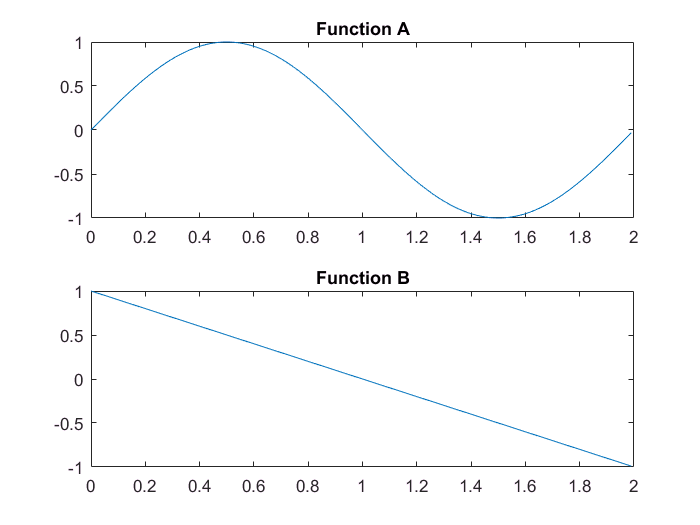

w0 = 2*pi/Time;
A  = sin(w0*t);
B  = 1 - t;

figure
subplot(2,1,1);
plot(t, A);
title('Function A');
subplot(2,1,2);
plot(t, B);
title('Function B');

Квадрат функций

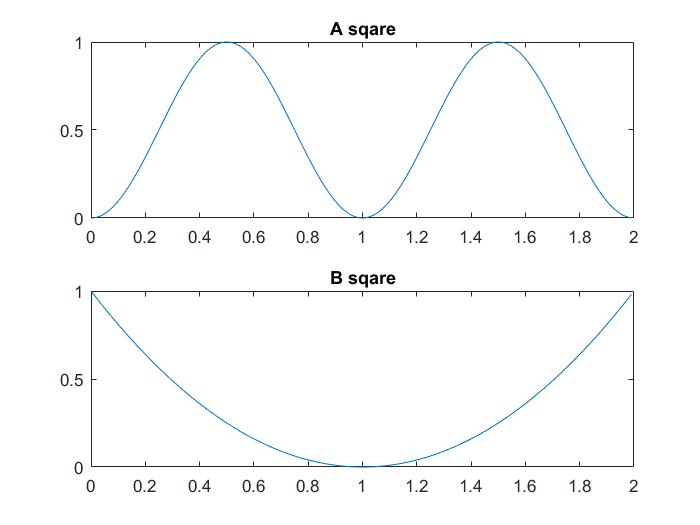

SqA = A.*A;
SqB = B.*B;

figure
subplot(2,1,1);
plot(t, SqA);
title('A sqare');
subplot(2,1,2);
plot(t, SqB);
title('B sqare')

Норма функций. Подобие интеграла.

NormA = sqrt(sum(SqA * dt));
NormB = sqrt(sum(SqB * dt));

Преобразование функций к нормированному виду

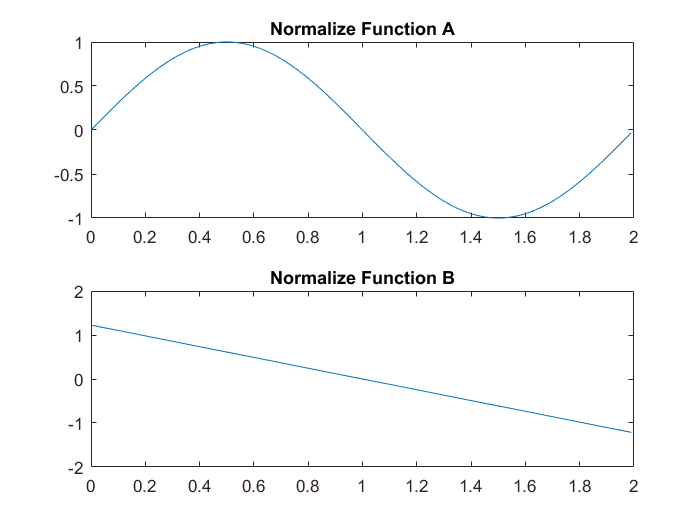

A = A/NormA;
B = B/NormB;

figure
subplot(2,1,1);
plot(t, A);
title('Normalize Function A');
subplot(2,1,2);
plot(t, B);
title('Normalize Function B');

Общий вид функций и графическое изображение разницы функций

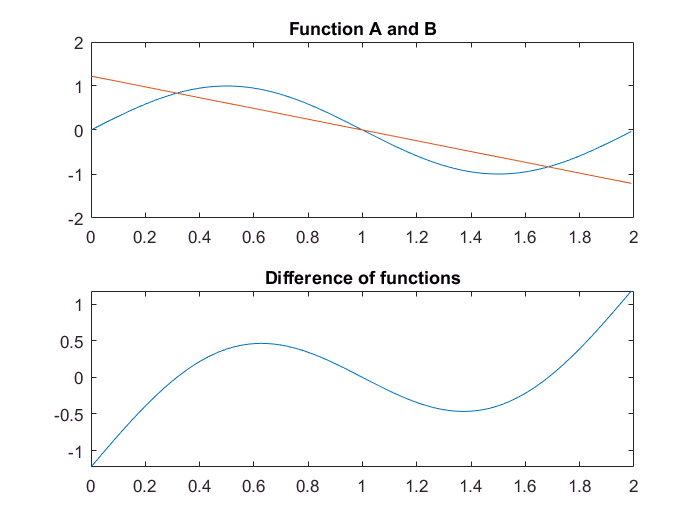

FunDif = A - B;

figure
subplot(2,1,1);
plot(t, A);
hold on
plot(t, B);
hold off
title('Function A and B');
subplot(2,1,2);
plot(t, FunDif);
title('Difference of functions');
ylim([min(FunDif) max(FunDif)]);

Расстояние между функциями

FunDistance = sum(FunDif.*FunDif * dt);
disp('Distance between functions is ');

Distance between functions is 


disp(FunDistance);

    0.4408



# Пример ортогональных функций

clear all
close all
clc

Time = 2;           % Time of signals 2 sec
Fs   = 100;         % Sampling frequency 100Hz
dt   = 1/Fs;        % Time step
N    = Time/dt;     % Number of samples

t = 0:dt:Time-dt;   % Time reprosontation

Создаю две функции

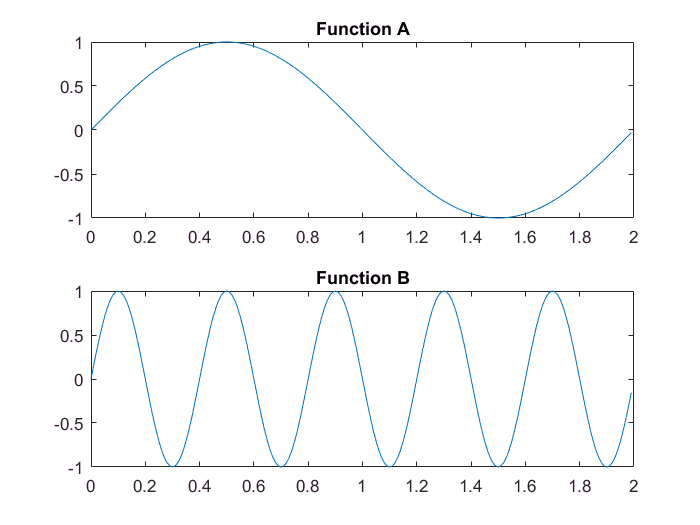

w0 = 2*pi/Time;
A  = sin(w0*t);
w1 = 5 * w0;
B  = sin(w1*t);

figure
subplot(2,1,1);
plot(t, A);
title('Function A');
subplot(2,1,2);
plot(t, B);
title('Function B');

Квадрат функций

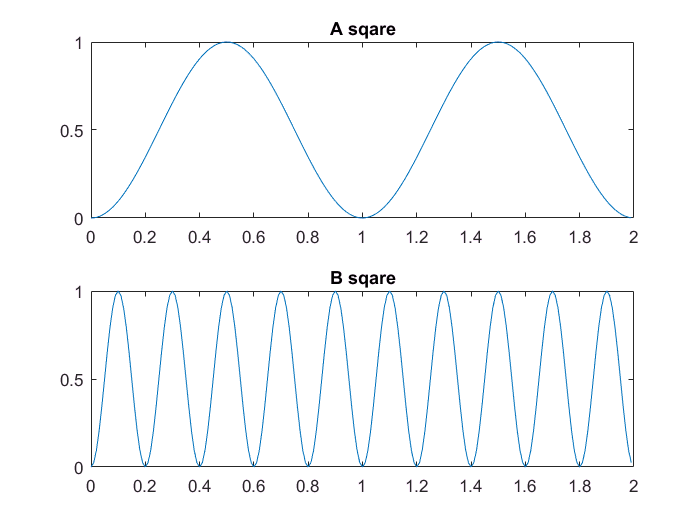

SqA = A.*A;
SqB = B.*B;

figure
subplot(2,1,1);
plot(t, SqA);
title('A sqare');
subplot(2,1,2);
plot(t, SqB);
title('B sqare')

Норма функций. Подобие интеграла.

NormA = sqrt(sum(SqA * dt));
NormB = sqrt(sum(SqB * dt));

Преобразование функций к нормированному виду

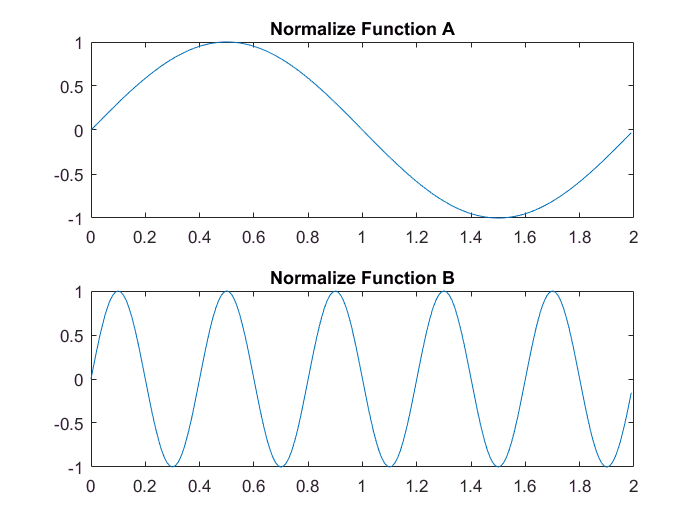

A = A/NormA;
B = B/NormB;

figure
subplot(2,1,1);
plot(t, A);
title('Normalize Function A');
subplot(2,1,2);
plot(t, B);
title('Normalize Function B');

Общий вид функций и графическое изображение разницы функций

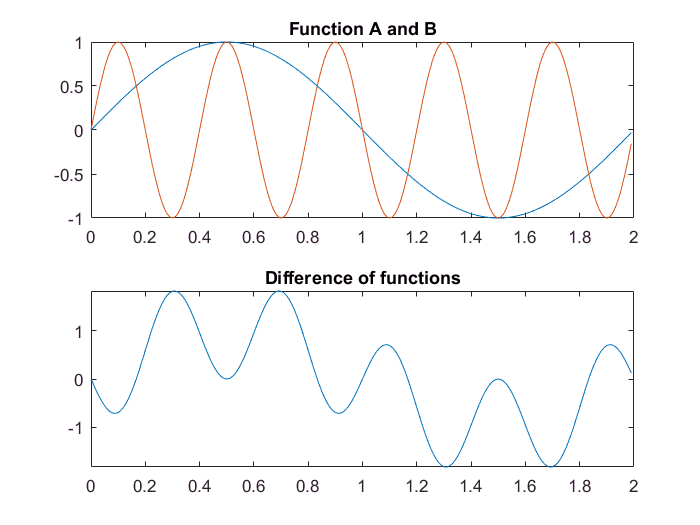

FunDif = A - B;

figure
subplot(2,1,1);
plot(t, A);
hold on
plot(t, B);
hold off
title('Function A and B');
subplot(2,1,2);
plot(t, FunDif);
title('Difference of functions');
ylim([min(FunDif) max(FunDif)]);

Расстояние между функциями

FunDistance = sum(FunDif.*FunDif * dt);
disp('Distance between functions is ');

Distance between functions is 


disp(FunDistance);

    2.0000



# Пример схожих функций

clear all
close all
clc

Time = 2;           % Time of signals 2 sec
Fs   = 100;         % Sampling frequency 100Hz
dt   = 1/Fs;        % Time step
N    = Time/dt;     % Number of samples

t = 0:dt:Time-dt;   % Time reprosontation

Создаю две функции

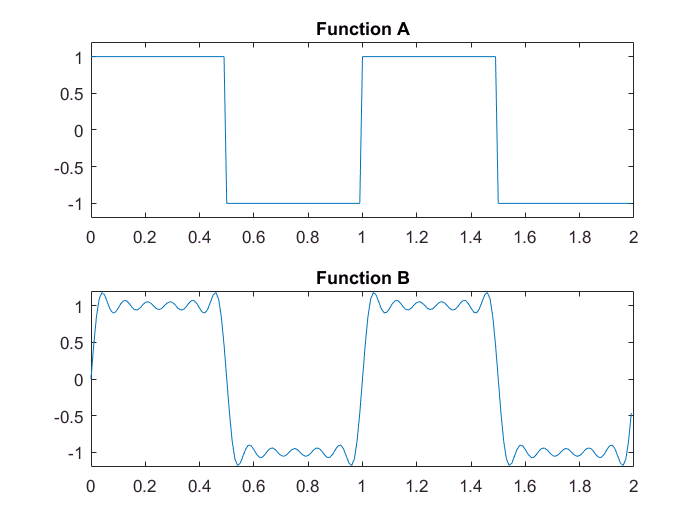

Period = N/2;
Hp     = Period/2;  % Half Period

A(1:Hp)      =  1;               % Fill half peroid with ones
A(Hp+1:2*Hp) = -1;               % Fill half period with minus ones
A            = repmat(A, 1, 2);  % Make 2 rows of that vector
A            = reshape(A, 1, N); % Combine it to one row vector 
                                 % So we fill 2 periods of function by copy

w0       = 2*pi / (Period*dt);   % Define base frequency
Am       = 1;                    % Define an Amplitude
Harmonic = [1 3 5 7 9 11];       % Define Harmonics that will be used
                                 % Calculate Function like Fourier Series
B  =  (1./Harmonic) * (Am*4/pi)*sin(w0*Harmonic'*t);   


figure
subplot(2,1,1);
plot(t, A);
title('Function A');
ylim([-1.2 1.2]);
subplot(2,1,2);
plot(t, B);
title('Function B');
ylim([-1.2 1.2]);

Квадрат функций

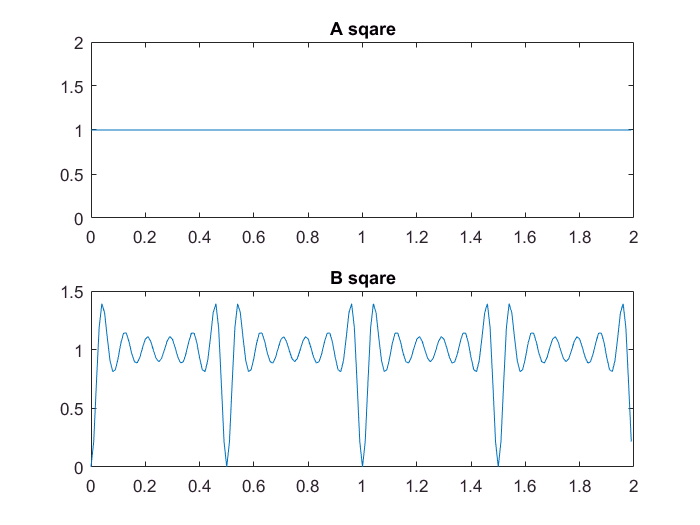

SqA = A.*A;
SqB = B.*B;

figure
subplot(2,1,1);
plot(t, SqA);
title('A sqare');
subplot(2,1,2);
plot(t, SqB);
title('B sqare');

Норма функций. Подобие интеграла.

NormA = sqrt(sum(SqA * dt));
NormB = sqrt(sum(SqB * dt));

Преобразование функций к нормированному виду

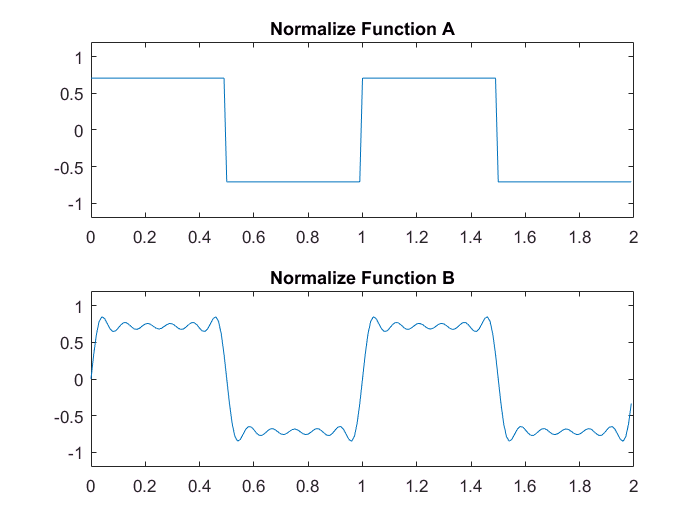

A = A/NormA;
B = B/NormB;

figure
subplot(2,1,1);
plot(t, A);
title('Normalize Function A');
ylim([-1.2 1.2]);
subplot(2,1,2);
plot(t, B);
title('Normalize Function B');
ylim([-1.2 1.2]);

Общий вид функций и графическое изображение разницы функций

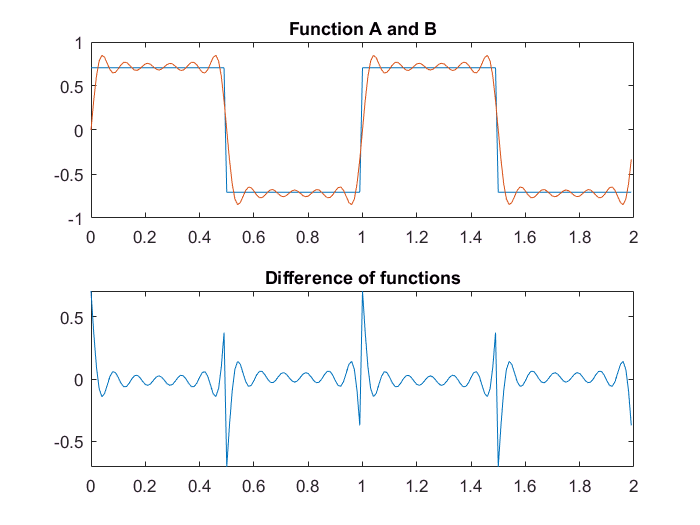

FunDif = A - B;

figure
subplot(2,1,1);
plot(t, A);
hold on
plot(t, B);
hold off
title('Function A and B');
subplot(2,1,2);
plot(t, FunDif);
title('Difference of functions');
ylim([min(FunDif) max(FunDif)]);

Расстояние между функциями

FunDistance = sum(FunDif.*FunDif * dt);
disp('Distance between functions is ');

Distance between functions is 


disp(FunDistance);

    0.0373



# Пример для копии функции

clear all
close all
clc

Time = 2;           % Time of signals 2 sec
Fs   = 100;         % Sampling frequency 100Hz
dt   = 1/Fs;        % Time step
N    = Time/dt;     % Number of samples

t = 0:dt:Time-dt;   % Time reprosontation

Создаю две функции

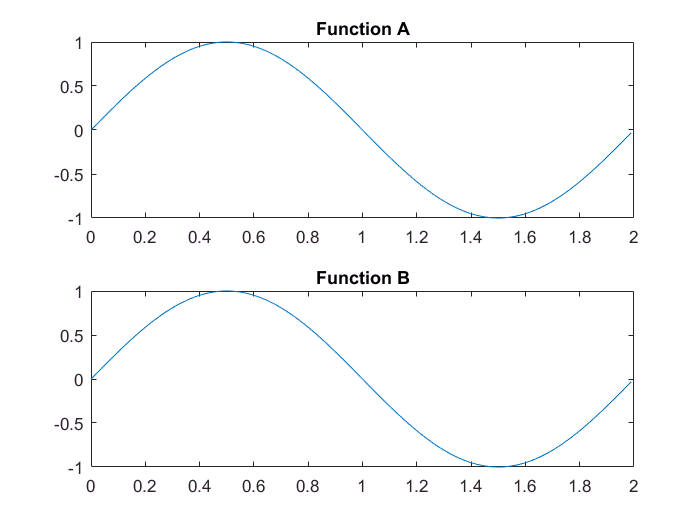

w0 = 2*pi/Time;
A  = sin(w0*t);

B  = A;

figure
subplot(2,1,1);
plot(t, A);
title('Function A');
subplot(2,1,2);
plot(t, B);
title('Function B');

Квадрат функций

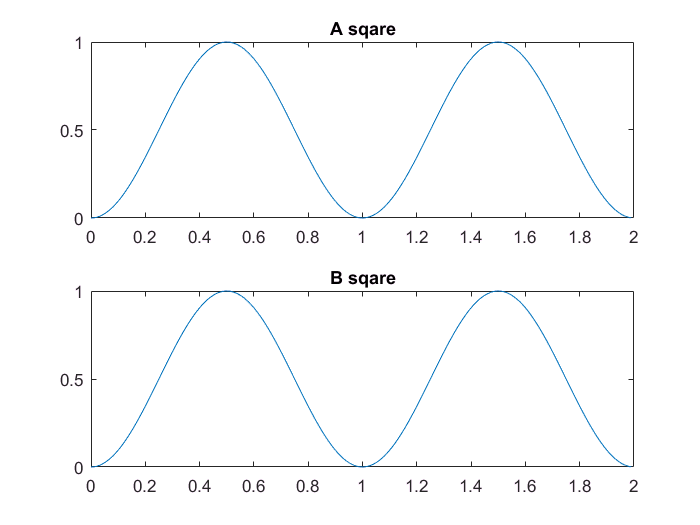

SqA = A.*A;
SqB = B.*B;

figure
subplot(2,1,1);
plot(t, SqA);
title('A sqare');
subplot(2,1,2);
plot(t, SqB);
title('B sqare')

Норма функций. Подобие интеграла.

NormA = sqrt(sum(SqA * dt));
NormB = sqrt(sum(SqB * dt));

Преобразование функций к нормированному виду

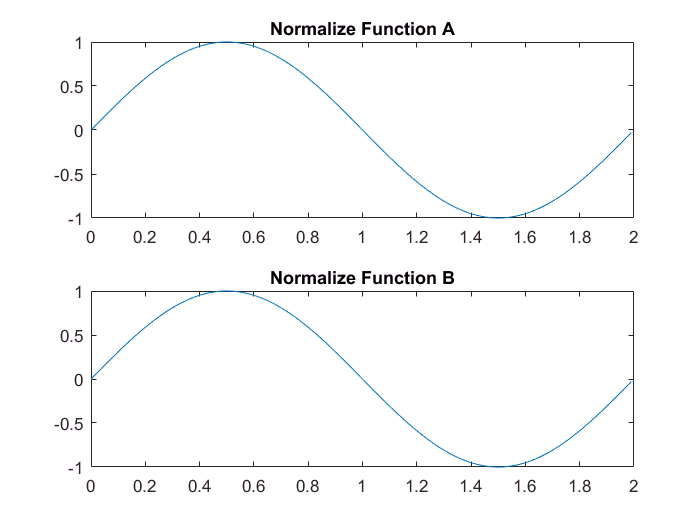

A = A/NormA;
B = B/NormB;

figure
subplot(2,1,1);
plot(t, A);
title('Normalize Function A');
subplot(2,1,2);
plot(t, B);
title('Normalize Function B');

Общий вид функций и графическое изображение разницы функций

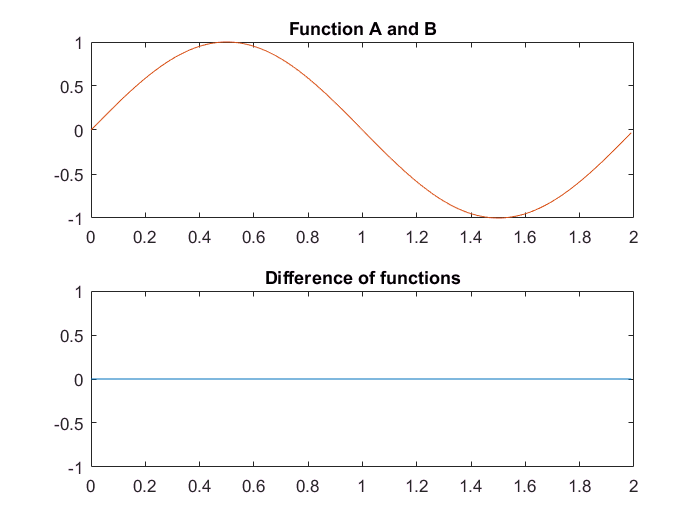

FunDif = A - B;

figure
subplot(2,1,1);
plot(t, A);
hold on
plot(t, B);
hold off
title('Function A and B');
subplot(2,1,2);
plot(t, FunDif);
title('Difference of functions');

Расстояние между функциями

FunDistance = sum(FunDif.*FunDif * dt);
disp('Distance between functions is ');

Distance between functions is 


disp(FunDistance);

     0

